% Define symbolic variables
syms X S P D S_feed real
mu_m = 0.48; % 1/h, maximum specific growth rate
P_m = 50; % g/L, product inhibition constant
K_m = 1.2; % g/L, Monod constant
K_i = 22; % g/L, inhibition constant for substrate
alpha = 2.2; % g/g, product yield coefficient
beta = 0.2; % 1/h, maintenance rate
Y_XS = 0.4; % g/g, yield coefficient

% Define mu function
mu = mu_m * (1 - P / P_m) * (S / (K_m + S + (S^2) / K_i));

% Define the system of ODEs
dXdt = -D * X + mu * X;
dSdt = D * (S_feed - S) - (1 / Y_XS) * mu * X;
dPdt = -D * P + (alpha * mu + beta) * X;

% State vector and input vector
state_vars = [X; S; P];
input_vars = [D; S_feed];

% Compute Jacobians
A = jacobian([dXdt; dSdt; dPdt], state_vars);
B = jacobian([dXdt; dSdt; dPdt], input_vars);

% Substitute the equilibrium point (X=6, S=5, P=19.14, D=0.2, S_feed=20)
A = double(subs(A, {X, S, P, D, S_feed}, {6, 5, 44.04, 0.0389, 20}));
B = double(subs(B, {X, S, P, D, S_feed}, {6, 5, 44.04, 0.0389, 20}));

% Define C and D matrices for output y = X
C = [1 0 0]; % Output is the first state (X)
D = [0 0]; % No direct influence of D or S_feed on output

% Create state-space system and compute transfer function
sys = ss(A, B, C, D);

% Convert to transfer function
sys_tf = tf(sys)

sys_tf =
 
  From input 1 to output:
        -6 s^2 + 0.7439 s + 0.03802
  ----------------------------------------
  s^3 + 0.1651 s^2 + 0.01616 s + 0.0004375
 
  From input 2 to output:
          1.579e-05 s + 6.142e-07
  ----------------------------------------
  s^3 + 0.1651 s^2 + 0.01616 s + 0.0004375
 
Continuous-time transfer function.


Ts1 = 0.5; 
Ts2 = 1.5; 

sys_d1 = c2d(tf(sys), Ts1, 'zoh') 

sys_d1 =
 
  From input 1 to output:
     -2.786 z^2 + 5.756 z - 2.965
  ----------------------------------
  z^3 - 2.917 z^2 + 2.838 z - 0.9208
 
  From input 2 to output:
  1.932e-06 z^2 - 2.996e-09 z - 1.856e-06
  ---------------------------------------
    z^3 - 2.917 z^2 + 2.838 z - 0.9208
 
Sample time: 0.5 seconds
Discrete-time transfer function.


sys_d2 = c2d(tf(sys), Ts2, 'zoh')

sys_d2 =
 
  From input 1 to output:
    -7.134 z^2 + 15.86 z - 8.615
  ---------------------------------
  z^3 - 2.748 z^2 + 2.53 z - 0.7807
 
  From input 2 to output:
  1.666e-05 z^2 - 7.491e-08 z - 1.475e-05
  ---------------------------------------
     z^3 - 2.748 z^2 + 2.53 z - 0.7807
 
Sample time: 1.5 seconds
Discrete-time transfer function.



% Display the results
disp('A matrix:');

A matrix:


disp(A);

    0.0001    0.0004   -0.0393
   -0.0975   -0.0399    0.0981
    0.2858    0.0009   -0.1253



disp('B matrix:');

B matrix:


disp(B);

   -6.0000         0
   15.0000    0.0389
  -44.0400         0



disp('C matrix:');

C matrix:


disp(C);

     1     0     0



disp('D matrix:');

D matrix:


disp(D);

     0     0



disp('Transfer function:');

Transfer function:


disp(sys_tf);

  1×2 tf array with properties:

       Numerator: {[0 -6.0000 0.7439 0.0380]  [0 0 1.5789e-05 6.1420e-07]}
     Denominator: {[1 0.1651 0.0162 4.3750e-04]  [1 0.1651 0.0162 4.3750e-04]}
        Variable: 's'
         IODelay: [0 0]
      InputDelay: [2×1 double]
     OutputDelay: 0
       InputName: {2×1 cell}
       InputUnit: {2×1 cell}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



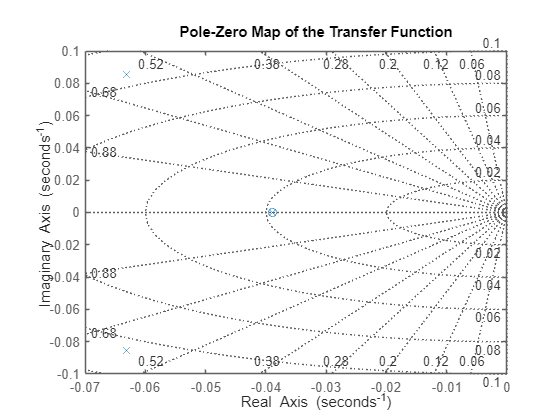


% Display poles and zeros (Pole-Zero Map)
figure;
pzmap(sys_tf);
grid on
title('Pole-Zero Map of the Transfer Function');